# Example script illustrating how to fit the SOC model

## Note

% This script assumes familiarity with the script that 
% illustrates how to fit the CSS model (cssmodel_example.m).

## Add code to the MATLAB path

savepath = fullfile(ap_root_path, 'HU_tutorials');
setup

## Load data

% load data from the third dataset
load('dataset03.mat','betamn','betase');

## Load stimuli

load('stimuli.mat','images');

## Perform stimulus pre-processing (Part 1)

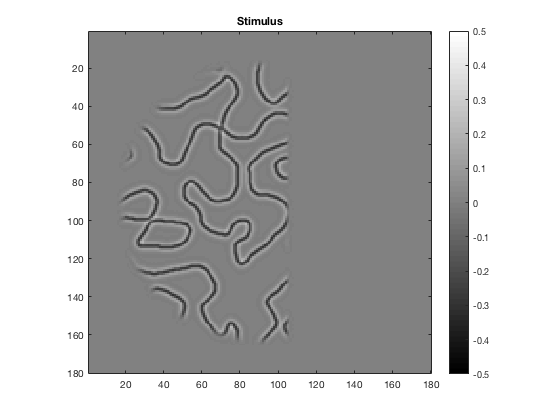

% extract the stimuli we need and then concatenate along the third dimension.
% (note that we fit only the first 99 (out of 156) stimuli;
% this corresponds to what was done in the paper.)
stimulus = images(69+(1:99));
stimulus = cat(3,stimulus{:});
clear images;

% resize the stimuli to 150 x 150 to reduce computational time.
% use single-format to save memory.
temp = zeros(150,150,size(stimulus,3),'single');
for p=1:size(stimulus,3)
  temp(:,:,p) = imresize(single(stimulus(:,:,p)),[150 150],'cubic');
end
stimulus = temp;
clear temp;

% ensure that all values are between 0 and 254.
% rescale values to the range [0,1].
% subtract off the background luminance (0.5).
% after these steps, all pixel values will be in the 
% range [-.5,.5] with the background corresponding to 0.
stimulus(stimulus < 0) = 0;
stimulus(stimulus > 254) = 254;
stimulus = stimulus/254 - 0.5;

% pad the stimulus with zeros (to reduce edge effects).
% the new resolution is 180 x 180 (15-pixel padding on each side).
stimulus = placematrix(zeros(180,180,size(stimulus,3),'single'),stimulus);

% inspect one of the stimuli
figure;
imagesc(stimulus(:,:,100));
axis image tight;
caxis([-.5 .5]);
colormap(gray);
colorbar;
title('Stimulus');

## Perform stimulus pre-processing (Part 2)

% thus far, we have performed very basic pre-processing of the stimulus.  now,
% we will proceed to perform more specialized operations that can be considered
% to be a more integral part of the SOC model.  the reason that we consider these
% operations to be "pre-processing" is these operations come before the 
% operations that we are primarily concerned with in this example script.
%
% essentially, the goal of this script is to fit certain model parameters; any 
% pre-computations we can perform prior to the fitting of these parameters 
% will help reduce computational time.

% apply Gabor filters to the stimuli.  filters occur at different positions, 
% orientations, and phases.  there are several parameters that govern the
% design of the filters:
%   the number of cycles per image is 37.5*(180/150)
%   the spatial frequency bandwidth of the filters is 1 octave
%   the separation of adjacent filters is 1 std dev of the Gaussian envelopes
%     (this results in a 90 x 90 grid of positions)
%   filters occur at 8 orientations
%   filters occur at 2 phases (between 0 and pi)
%   the Gaussian envelopes are thresholded at .01
%   filters are scaled to have an equivalent Michelson contrast of 1
%   the dot-product between each filter and each stimulus is computed
% after this step, stimulus is images x phases*orientations*positions.
if exist(fullfile(savepath, 'stimulusFiltered.mat'), 'file')
    load (fullfile(savepath, 'stimulusFiltered.mat'));
else
    stimulusFiltered = applymultiscalegaborfilters(reshape(stimulus,180*180,[])', ...
        37.5*(180/150),-1,1,8,2,.01,2,0);
    save(fullfile(savepath, 'stimulusFiltered.mat'), 'stimulusFiltered')
end

## Energy computation

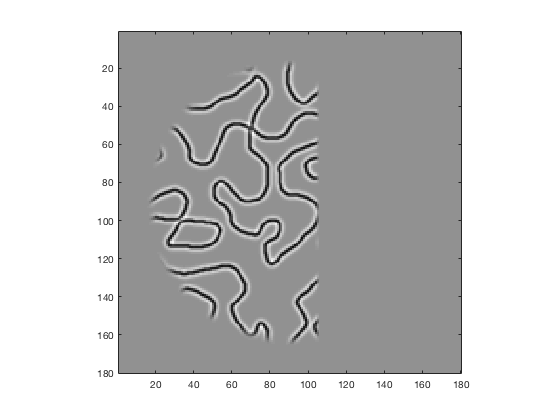

% compute the square root of the sum of the squares of the outputs of 
% quadrature-phase filter pairs (this is the standard complex-cell energy model).
% after this step, stimulus is images x orientations*positions.
stimulusEnergy = sqrt(blob(stimulusFiltered.^2,2,2));

% Check an exmaple
figure, imagesc(stimulus(:,:,100)); axis image; colormap gray;

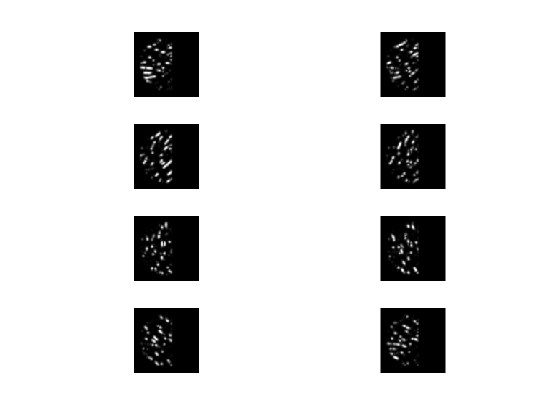

s = reshape(stimulusEnergy, [891 8 90 90]);
figure,  for ii = 1:8; subplot(4,2,ii); a = squeeze(s(100,ii,:,:)); imagesc(a); axis image off; colormap gray; end

clear s a;


## Divisive normalization

% compute the population term in the divisive-normalization equation.

% this term is simply the average across the complex-cell outputs 
% at each position (averaging across orientation).
stimulusPOP = blob(stimulusEnergy,2,8)/8;

% repeat the population term for each of the orientations
stimulusPOP = upsamplematrix(stimulusPOP,8,2,[],'nearest');

% apply divisive normalization to the complex-cell outputs.  there are two parameters
% that influence this operation: an exponent term (r) and a semi-saturation term (s).  
% the parameter values specified here were determined through a separate fitting 
% procedure (see paper for details).  for the purposes of this script, we will 
% simply hard-code the parameter values here and not worry about attempting to fit 
% the parameters.
r = 1;
s = 0.5;
stimulusDivNorm = stimulusEnergy.^r ./ (s.^r + stimulusPOP.^r);
clear stimulusPOP;


## sum across orientation.  after this step, stimulus is images x positions.

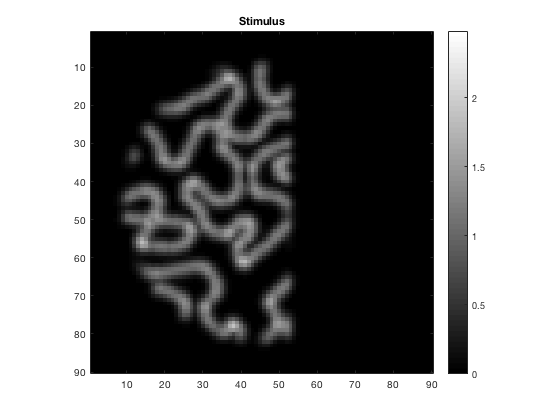


stimulusSummed = blob(stimulusDivNorm,2,8);

% each of the 99 stimuli that we are considering actually consists of 9 frames.
% we will be handling this by computing, for each stimulus, the predicted response 
% for each of the 9 frames and then averaging across these predicted responses.
% the legwork for doing this is handled by the fitting function we will be using,
% fitnonlinearmodel.m.  that function requires that the individual frames that comprise
% a single stimulus be arranged along the third dimension, so that is now what we do.

% reshape stimuli into desired format: 99 stimuli x 90*90 positions x 9 frames.
stimulusSummed = permute(reshape(stimulusSummed,9,99,8100),[2 3 1]);

% inspect one of the stimuli
figure;
mx = max(abs(stimulusSummed(:)));
imagesc(reshape(stimulusSummed(12,:,1),[90 90]));
axis image tight;
caxis([0 mx]);
colormap(gray);
colorbar;
title('Stimulus');

% notice that the stimulus is now a "contrast image" where each value indicates
% the amount of local contrast at a particular location in the stimulus.

## Prepare for model fitting

% to prepare for the call to fitnonlinearmodel.m, we have to define various 
% input parameters.  this is what we will now do.

% define constants
res = 90;  % resolution of the pre-processed stimuli

% in this example script, we will be fitting only some of the parameters of the
% SOC model.  the other parameters have already been fixed (see above).
%
% the parameters that we will be fitting are [R C S G N C] where
%   R is the row index of the center of the 2D Gaussian
%   C is the column index of the center of the 2D Gaussian
%   S is the standard deviation of the 2D Gaussian
%   G is a gain parameter
%   N is the exponent of the power-law nonlinearity
%   C is a parameter that controls the strength of second-order contrast

% define initial seeds for model parameters.  to help avoid the problem of 
% local minima, we will start at several different initial seeds (corresponding to
% different combinations of N and C), and we will choose the model that 
% achieves the best fit to the data.
Ns = [.05 .1 .3 .5];
Cs = [.4 .7 .9 .95];
seeds = [];
for p=1:length(Ns)
  for q=1:length(Cs)
    seeds = cat(1,seeds,[(1+res)/2 (1+res)/2 res/4*sqrt(0.5) 10 Ns(p) Cs(q)]);
  end
end

% define bounds for the model parameters
bounds = [1-res+1 1-res+1 0   -Inf 0   0;
          2*res-1 2*res-1 Inf  Inf Inf 1];

% define a version of bounds where we insert NaNs in the first row
% in the spots corresponding to the N and C parameters.  this 
% indicates to fix these parameters and not optimize them.
boundsFIX = bounds;
boundsFIX(1,5:6) = NaN;

% issue a dummy call to makegaussian2d.m to pre-compute xx and yy.
% these variables are re-used to achieve faster computation.
[d,xx,yy] = makegaussian2d(res,2,2,2,2);

% define a helper function that we will use for the SOC model.
% this function accepts stimuli (dd, a matrix of size A x 90*90),
% weights (wts, a vector of size 90*90 x 1), and a parameter
% (c, a scalar) and outputs a measure of variance (as a vector
% of size A x 1).  intuitively, this function computes
% a weighted average, subtracts that off, squares, and 
% computes a weighted sum.
socfun = @(dd,wts,c) bsxfun(@minus,dd,c*(dd*wts)).^2 * wts;

% define another helper function.  given a set of parameters,
% this function outputs a 2D Gaussian (as a vector of size 90*90 x 1)
gaufun = @(pp) vflatten(makegaussian2d(res,pp(1),pp(2),pp(3),pp(3),xx,yy,0,0)/(2*pi*pp(3)^2));

% we will now define a function that implements the SOC model.  this function
% accepts a set of parameters (pp, a vector of size 1 x 6) and a set of stimuli
% (dd, a matrix of size A x 90*90) and outputs the predicted response to those
% stimuli (as a vector of size A x 1).  
modelfun = @(pp,dd) pp(4)*(socfun(dd,gaufun(pp),restrictrange(pp(6),0,1)).^pp(5));

% notice that in the above function, we use restrictrange to force C to be 
% between 0 and 1.  this is necessary because even though we defined bounds 
% for the parameters (see above), we will be using the Levenberg-Marquardt 
% optimization algorithm, which does not respect parameter bounds.  

% we are ready to define the final model specification.  in the following, 
% we specify a stepwise fitting scheme.  in the first fit (the first row), 
% we start at the seed and optimize all parameters except the N and C parameters.
% in the second fit (the second row), we start at the parameters estimated in 
% the first fit and optimize all parameters.  the reason that the first entry
% is [] is that we will be using a mechanism that evaluates multiple initial
% seeds, and in that case the first entry here is ignored.
model = {{[]         boundsFIX   modelfun} ...
         {@(ss) ss   bounds      @(ss) modelfun}};

% define optimization options (these are added on top of 
% the default options used in fitnonlinearmodel.m)
optimoptions = {'Algorithm' 'levenberg-marquardt' 'Display' 'off'};

% define the resampling scheme to use.  here, we use 0, which
% means to just fit the data (no cross-validation nor bootstrapping).
resampling = 0;

% define the metric that we will use to quantify goodness-of-fit.
metric = @(a,b) calccod(a,b,[],[],0);

% specify the index of the voxel to fit
ix = 204;

% finally, construct the options struct that will be passed to fitnonlinearmodel.m
opt = struct( ...
  'stimulus',     stimulusSummed, ...
  'data',         betamn(ix,1:99)', ...
  'model',        {model}, ...
  'seed',         seeds, ...
  'optimoptions', {optimoptions}, ...
  'resampling',   resampling, ...
  'metric',       metric);

% do a quick inspection of opt
opt

opt = struct with fields:
        stimulus: [99×8100×9 single]
            data: [99×1 double]
           model: {{1×3 cell}  {1×3 cell}}
            seed: [16×6 double]
    optimoptions: {'Algorithm'  'levenberg-marquardt'  'Display'  'off'}
      resampling: 0
          metric: @(a,b)calccod(a,b,[],[],0)


## Fit the model

results = fitnonlinearmodel(opt);

*** fitnonlinearmodel: started at 28-Apr-2018 20:57:36. ***
*** fitnonlinearmodel: outputdir = , chunksize = 1, chunknum = 1
Starting parallel pool (parpool) using the 'local' profile ...
connected to 2 workers.
*** fitnonlinearmodel: processing voxel 1 (1 of 1). ***
  starting resampling case 1 of 1.
    trying seed 1 of 16.
      for model 1 of 2, the seed is [45.500 45.500 15.910 10.000 0.050 0.400 ].
      the estimated parameters are [71.512 80.354 3.809 6.506 0.050 0.400 ].
      for model 2 of 2, the seed is [71.512 80.354 3.809 6.506 0.050 0.400 ].
      the estimated parameters are [71.512 80.354 3.809 6.506 0.050 0.400 ].
    trying seed 2 of 16.
      for model 1 of 2, the seed is [45.500 45.500 15.910 10.000 0.050 0.700 ].
      the estimated parameters are [55.777 59.520 0.902 6.484 0.050 0.700 ].
      for model 2 of 2, the seed is [55.777 59.520 0.902 6.484 0.050 0.700 ].
      the estimated parameters are [54.020 57.437 1.520 8.630 0.158 0.842 ].
    trying seed 3 of 16

## Inspect the results

% these are the final parameter estimates
results.params

ans =    53.7344   58.7237    1.5545    9.5016    0.1763    0.8758


% this is the R^2 between the model fit and the data
results.trainperformance

ans = 95.2858

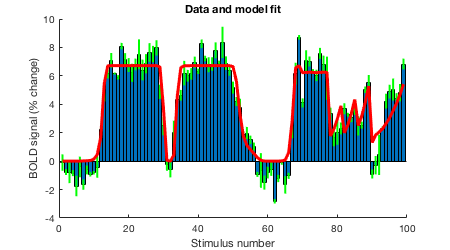

% visualize the data and the model fit
figure; setfigurepos([100 100 450 250]); hold on;
bar(betamn(ix,1:99),1);
errorbar2(1:99,betamn(ix,1:99),betase(ix,1:99),'v','g-','LineWidth',2);
modelfit = [];
for p=1:9
  modelfit(:,p) = modelfun(results.params,stimulusSummed(:,:,p));
end
plot(1:99,mean(modelfit,2),'r-','LineWidth',3);
ax = axis;
axis([0 100 ax(3:4)]);
xlabel('Stimulus number');
ylabel('BOLD signal (% change)');
title('Data and model fit');